# Computational Essay (Draft 1)

*Authors:* Murray Chen, Thandetch Mateedunsatits 

Date: September 28, 2025

### **Question**

Modelling Question: Can we effectively model the first wave of COVID in Singapore from the dates Janurary 23 to December 31.

**Background**

We simulate a discrete-time SIRD model the entire year. A mask intervention halves the infection rate β starting on day 30. We examine how this policy changes the epidemic trajectory of susceptible, infected, recovered, and deceased populations.

The SIR framework partitions the population into Susceptible (S), Infected (I), and Recovered (R). We also track Deaths (D). Interventions (e.g., mask adoption) reduce the infection rate β. Our aim is : show how a mid-course β reduction flattens infections during a first wave which helps us to predict the real world.

**Modeling**

We made the following assumptiosn in our model:

(a) Closed population: no births or migration, so the population is S+I+R+D.

(b) Most singaporeans only started wearing masks and saw the impact of intervention from day 30 onward. β is halved.

**Methodology/Model**

tab_data = readtable("Singapore_data.csv", "Delimiter", ",")

tab_data = 366×5 table
    Day    Infected    Recovered    Dead    Total
    ___    ________    _________    ____    _____

     1        0            0         0        0  
     2        0            0         0        0  
     3        0            0         0        0  
     4        0            0         0        0  
     5        0            0         0        0  
     6        0            0         0        0  
     7        0            0         0        0  
     8        0            0         0        0  
     9        0            0         0        0  
    10        0            0         0        0  
    11        0            0         0        0  
    12        0            0         0        0  
    13        0            0         0        0  
    14        0            0         0        0  
    15

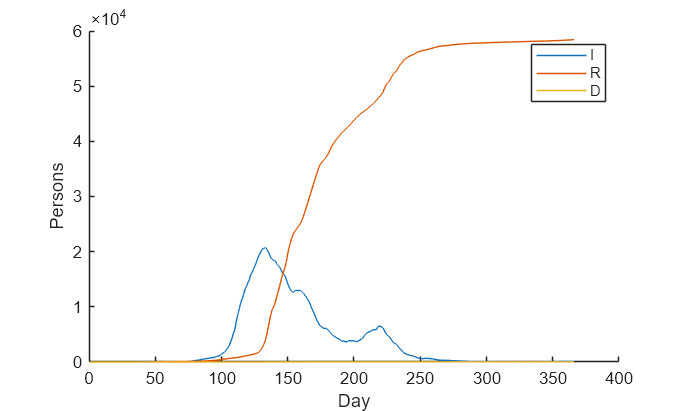

% Unpack the table
W_data = tab_data.Day;
I_data = tab_data.Infected;
R_data = tab_data.Recovered;
D_data = tab_data.Dead;

%plot(W_data, S_fix, 'DisplayName', 'S')
% Plot the actual data for comparison
figure()
%plot(W_fix, 50000, 'k-', 'DisplayName', 'Total')
hold on
plot(W_data, I_data, 'DisplayName', 'I')
plot(W_data, R_data, 'DisplayName', 'R')
plot(W_data, D_data, 'DisplayName', 'D')
xlabel("Day")
ylabel("Persons")
legend()


%S_fix
%I_fix
%R_fix
%T_fix 

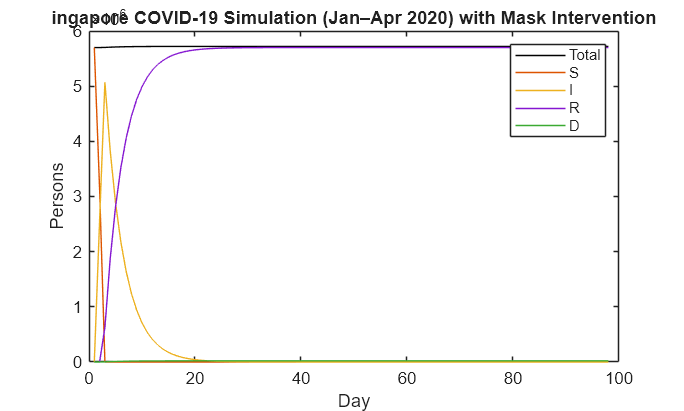

% How could we model Covid19 in Singapre
% variables, immune, not immune.
% dynamic intervention variables 

beta_base = 0.45;              % initial infectioon rate
intervention_factor = 0.5;      % intervention rate
intervention_day = 30;  
beta = beta_base * (1 - intervention_factor);
gamma = 0.245; % Recovery rate (1 / day)
mu = 0.0009;                   % death rate
i_1 = 1;                       
n_total = 5700000;             % population
week_end = 14;                 % 14weeks 

% Define initial state
s_1 = n_total - i_1;
r_1 = 0;
d_1 = 0;


[S_fix, I_fix, R_fix, D_fix, W_fix] = simulate_sir(s_1, i_1, r_1, d_1, beta_base, gamma, mu, week_end * 7, intervention_day, intervention_factor);
T_fix = S_fix + I_fix + R_fix + D_fix;

% NOTE: Do not edit this code; Plot multiple diagnostic quantities
figure()
plot(W_fix, T_fix, 'k-', 'DisplayName', 'Total'); hold on
plot(W_fix, S_fix, 'DisplayName', 'S')
plot(W_fix, I_fix, 'DisplayName', 'I')
plot(W_fix, R_fix, 'DisplayName', 'R')
plot(W_fix, D_fix, 'DisplayName', 'D')
%S_fix
%I_fix
%R_fix
%T_fix 

xlabel("Day")
ylabel("Persons")
legend()
title("ingapore COVID-19 Simulation (Jan–Apr 2020) with Mask Intervention")